## 微分方程

### 微分方程解析解

求$$\frac { \mathrm { d } u } { \mathrm { d } t } = 1 + u ^ { 2 }$$的解析解

s1 = dsolve('Du=1+u^2','t')

$$s1 = \left(\begin{array}{c} \tan\left(C_{2}+t\right)\\ \mathrm{i}\\ -\mathrm{i} \end{array}\right)$$


$${ \frac { d ^ { 2 } y } { d x ^ { 2 } } + 4 \frac { d y } { d x } + 29 y = 0 } 
,{ y (0 ) = 0 , y ^ { \prime } (0 ) = 15 } 
\end{ array} \ right$$$


s2 = dsolve('D2y+4*Dy+29*y=0','y(0)=0','Dy(0)=15','x')

$$s2 = 3\,\sin\left(5\,x\right)\,{\mathrm{e}}^{-2\,x}$$

求下列方程的通解


$$$\left\{\begin{array}{|} { \frac { d x } { d t } = 2 x - 3 y + 3 z } \\ { \frac { d y } { d t } = 4 x - 5 y + 3 z } \\ { \frac { d z } { d t } = 4 x - 4 y + 2 z } \end{array}$$$


[x3, y3, z3] = dsolve('Dx=2*x-3*y+3*z','Dy=4*x-5*y+3*z', 'Dz=4*x-4*y+2*z', 't')

$$x3 = C_{11}\,{\mathrm{e}}^{2\,t}+C_{12}\,{\mathrm{e}}^{-t}$$

$$y3 = C_{11}\,{\mathrm{e}}^{2\,t}+C_{12}\,{\mathrm{e}}^{-t}+C_{13}\,{\mathrm{e}}^{-2\,t}$$

$$z3 = C_{11}\,{\mathrm{e}}^{2\,t}+C_{13}\,{\mathrm{e}}^{-2\,t}$$

### 微分方程数值解

t: 自变量值

x: 函数值

ode35: ode23,ode11,3ode1

f:函数

ts: [t0, tf] 取值区间

x0: 函数初值

options: 设定误差限

#### 注意:

高阶方程等价为一阶方程

#### eg:

求以下方程数值解


$$$\left\{ \begin{array} { c } { \frac { \mathrm { d } ^ { 2 } x } { \mathrm { d } t ^ { 2 } } -1000 \left(1 -x ^ { 2 } \right) \frac { \mathrm { d } x } { \mathrm { d } t } -x = 0 } \\ { x (0 ) = 2 ; x ^ { \prime } (0 ) = 0 } \end{array} \right.$$$


令*y*`1=`*x*`，`*y*`2=`*y*`1’`

`微分方程转换成一阶微分方程组`

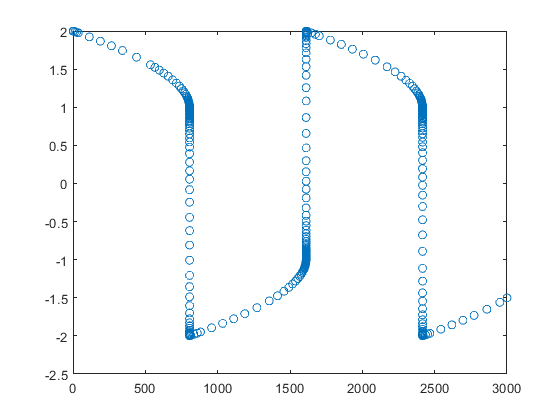

[t4,y4] = ode15s('vdp1000',[0,3000],[2,0]);
figure
plot(t4,y4(:,1),'o')

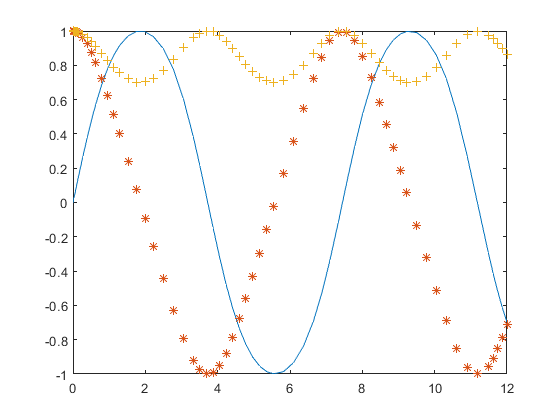

[t5,y5] = ode45('rigid',[0,12],[0,1,1]);
figure
plot(t5,y5(:,1),'-', t5,y5(:,2),'*', t5,y5(:,3),'+')

s3 = dsolve('(1-x)*D2y=(1+(Dy)^2)^(1/2)*(1/5)','y(0)=0','Dy(0)=0','x')

$$s3 = \begin{array}{l} \left(\begin{array}{c} -\frac{5\,\sigma_{5}\,\sigma_{3}}{8}-\frac{5\,\sigma_{4}\,\sigma_{2}}{12}-\frac{5}{24}\\ \frac{5\,\sigma_{3}}{8\,\sigma_{1}}-\frac{5\,\sigma_{1}\,\sigma_{2}}{12}-\frac{5\,\sigma_{5}\,\sigma_{1}}{12}-\frac{5\,\sigma_{4}}{8\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-{\left(-1\right)}^{3/5}}\\ \sigma_{2}={\left(x-1\right)}^{6/5}\\ \sigma_{3}={\left(x-1\right)}^{4/5}\\ \sigma_{4}={\left(-1\right)}^{4/5}\\ \sigma_{5}={\left(-1\right)}^{1/5} \end{array}$$

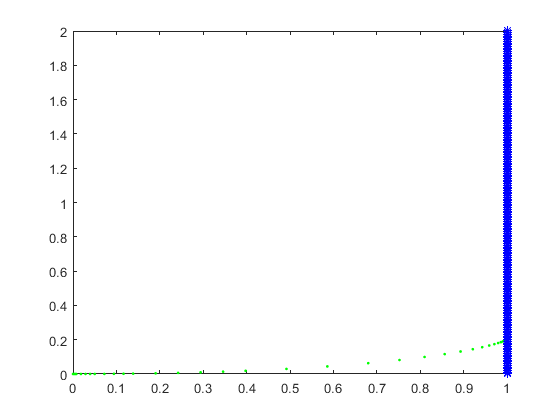

clear
[x6,y6] = ode15s('missile1',[0,0.999],[0,0]);
figure
plot(x6,y6(:,1),'g.');
hold on
y7 = 0:0.01:2;
plot(1,y7,'b*')

figure
[t8,y8] = ode45('missile2',[0,2],[0,0]);

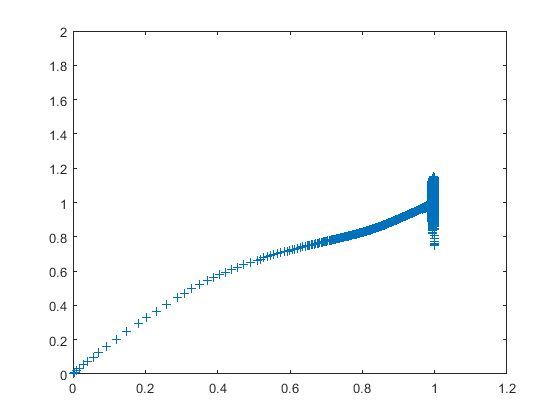

plot(y8(:,1),y8(:,2),'+')
hold on
Y8 = 0:0.01:2;
plot(1,Y8,'-')